%LQR CONTROLLER DESIGN for Linear and Non Linear System
%Linearized Model is from Jacobian Linearization.

clc;
clear all;
close all;
syms x x_dot theta1 theta_dot_1 theta2 theta_dot_2 F M m1 m2 g l1 l2


x_ddot = (F-(m1*sin(theta1))*(g*cos(theta1)+l1*theta_dot_1*theta_dot_1)-m2*sin(theta2)*(g*cos(theta2)+l2*theta_dot_2*theta_dot_2))/(M+m1*sin(theta1)*sin(theta1)+m2*sin(theta2)*sin(theta2));
theta1_ddot = (x_ddot*cos(theta1)-g*sin(theta1))/l1;
theta2_ddot = (x_ddot*cos(theta2)-g*sin(theta2))/l2;


A_intermediate = [diff(x_dot,x) diff(x_dot,x_dot) diff(x_dot,theta1) diff(x_dot,theta_dot_1) diff(x_dot,theta2) diff(x_dot,theta_dot_2);
    diff(x_ddot,x) diff(x_ddot,x_dot) diff(x_ddot,theta1) diff(x_ddot,theta_dot_1) diff(x_ddot,theta2) diff(x_ddot,theta_dot_2);
    diff(theta_dot_1,x) diff(theta_dot_1,x_dot) diff(theta_dot_1,theta1) diff(theta_dot_1,theta_dot_1) diff(theta_dot_1,theta2) diff(theta_dot_1,theta_dot_2);
    diff(theta1_ddot,x) diff(theta1_ddot,x_dot) diff(theta1_ddot,theta1) diff(theta1_ddot,theta_dot_1) diff(theta1_ddot,theta2) diff(theta1_ddot,theta_dot_2);
    diff(theta_dot_2,x) diff(theta_dot_2,x_dot) diff(theta_dot_2,theta1) diff(theta_dot_2,theta_dot_1) diff(theta_dot_2,theta2) diff(theta_dot_2,theta_dot_2);
    diff(theta2_ddot,x) diff(theta2_ddot,x_dot) diff(theta2_ddot,theta1) diff(theta2_ddot,theta_dot_1) diff(theta2_ddot,theta2) diff(theta2_ddot,theta_dot_2);
    ];
A = subs(A_intermediate,[x,x_dot,theta1,theta_dot_1,theta2,theta_dot_2],[0,0,0,0,0,0]);
B = [x_dot;x_ddot;theta_dot_1;theta1_ddot;theta_dot_2;theta2_ddot];
B = subs(B,[x,x_dot,theta1,theta_dot_1,theta2,theta_dot_2,F],[0,0,0,0,0,0,1]);

A1 = subs(A,[M,m1,m2,l1,l2,g],[1000,100,100,20,10,9.8]);
% A = vpa(A)
%Initial Eigen Values of the Linearized System
eigen_values = vpa(eig(A1))

$$eigen\_values = \left(\begin{array}{c} 0\\ 0\\ 1.0424809393673408583055086703293\,\mathrm{i}\\ 0.7281713335855694017848570773643\,\mathrm{i}\\ -1.0424809393673408583055086703293\,\mathrm{i}\\ -0.7281713335855694017848570773643\,\mathrm{i} \end{array}\right)$$



%Calculating the initial state response
C = eye(6)

C =      1     0     0     0     0     0
     0     1     0     0     0     0
     0     0     1     0     0     0
     0     0     0     1     0     0
     0     0     0     0     1     0
     0     0     0     0     0     1


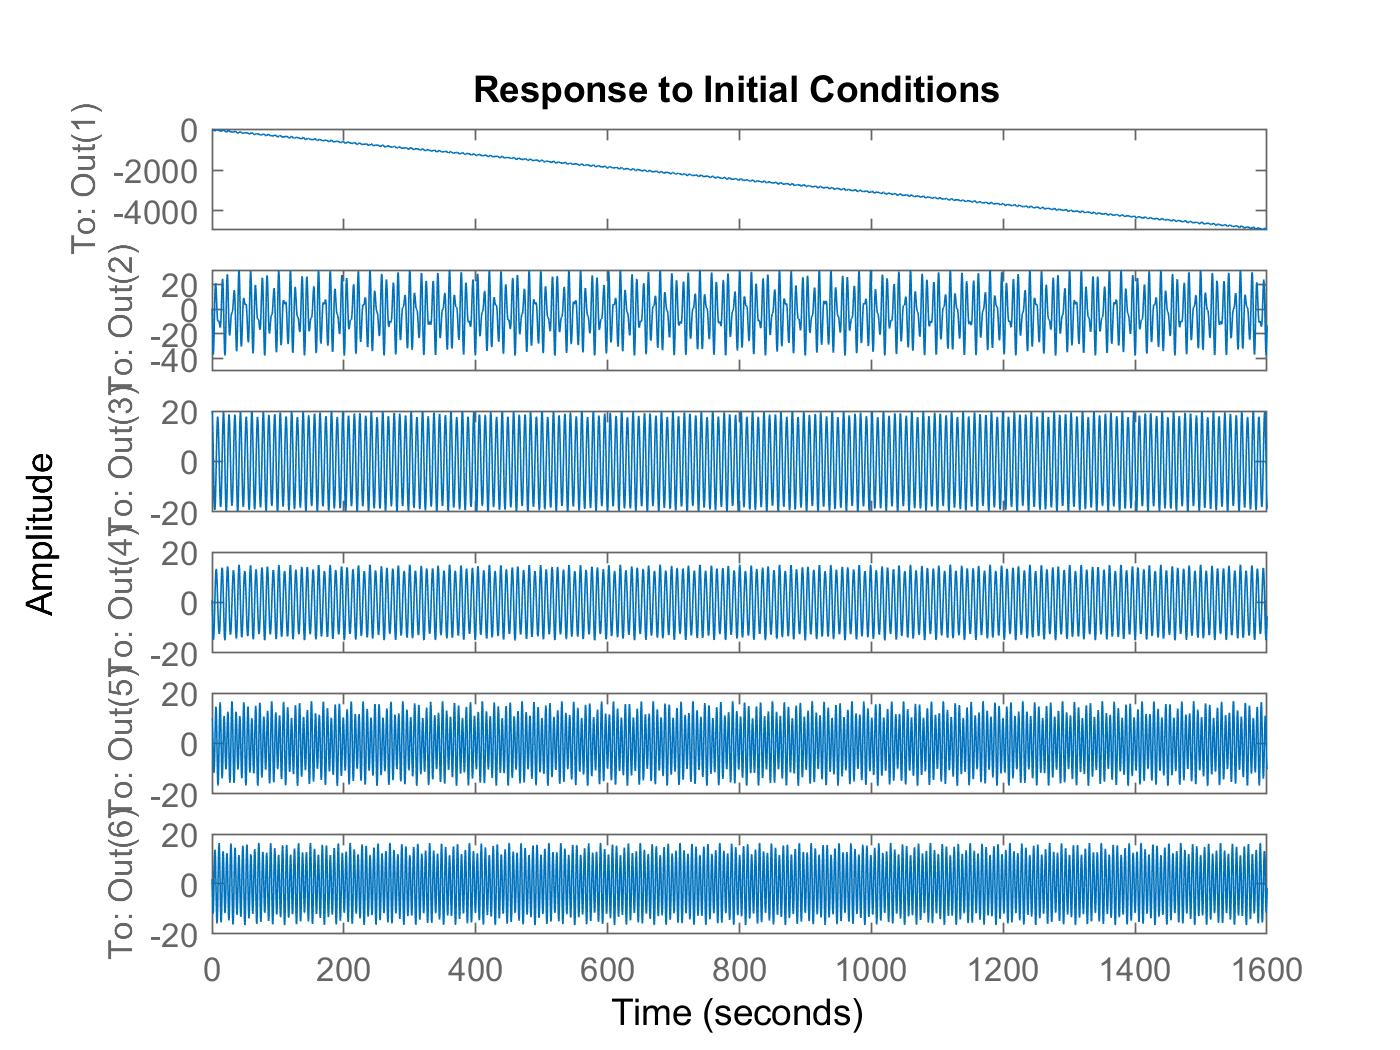

D = 0;
%Taking step input = F=1;
% vpa(A1);
New_A = [0 1 0 0 0 0; 0 0 -0.98 0 -0.98 0; 0 0 0 1 0 0;0 0 -0.539 0 -0.049 0;0 0 0 0 0 1;0 0 -0.098 0 -1.078 0];
% B = subs(B,[F,M,l1,l2],[1,1000,20,10]);
vpa(B);
New_B = [0;0.001;0;0.00005;0;0.0001];
initial_state = [3,0.3,20,1,10,2];
% Initial State Response
state_space = ss(New_A,New_B,C,D);
figure
initial(state_space,initial_state);

Q = [1 0 0 0 0 0;0 1 0 0 0 0;0 0 0.5 0 0 0;0 0 0 0.5 0 0;0 0 0 0 0.2 0;0 0 0 0 0 0.2];
R = 10;
% The below for loop is used for calculating the response of the system for
% different Q values and Different R Values to minimize the cost function

% for mult = 1:100:2000
%     figure
%     [K,P,Poles] = lqr(New_A,New_B,Q*2000,(R/mult)*100);
%     state_space = ss(New_A-(New_B*K),zeros(6,1),C,D)
%     initial(state_space,initial_state)
% end

figure
[K,P,Poles] = lqr(New_A,New_B,Q*20000,R/10000);
eig(New_A-(New_B*K))

ans =   -4.3249 + 0.0000i
  -1.0325 + 0.0000i
  -0.0232 + 0.9902i
  -0.0232 - 0.9902i
  -0.0127 + 0.7000i
  -0.0127 - 0.7000i


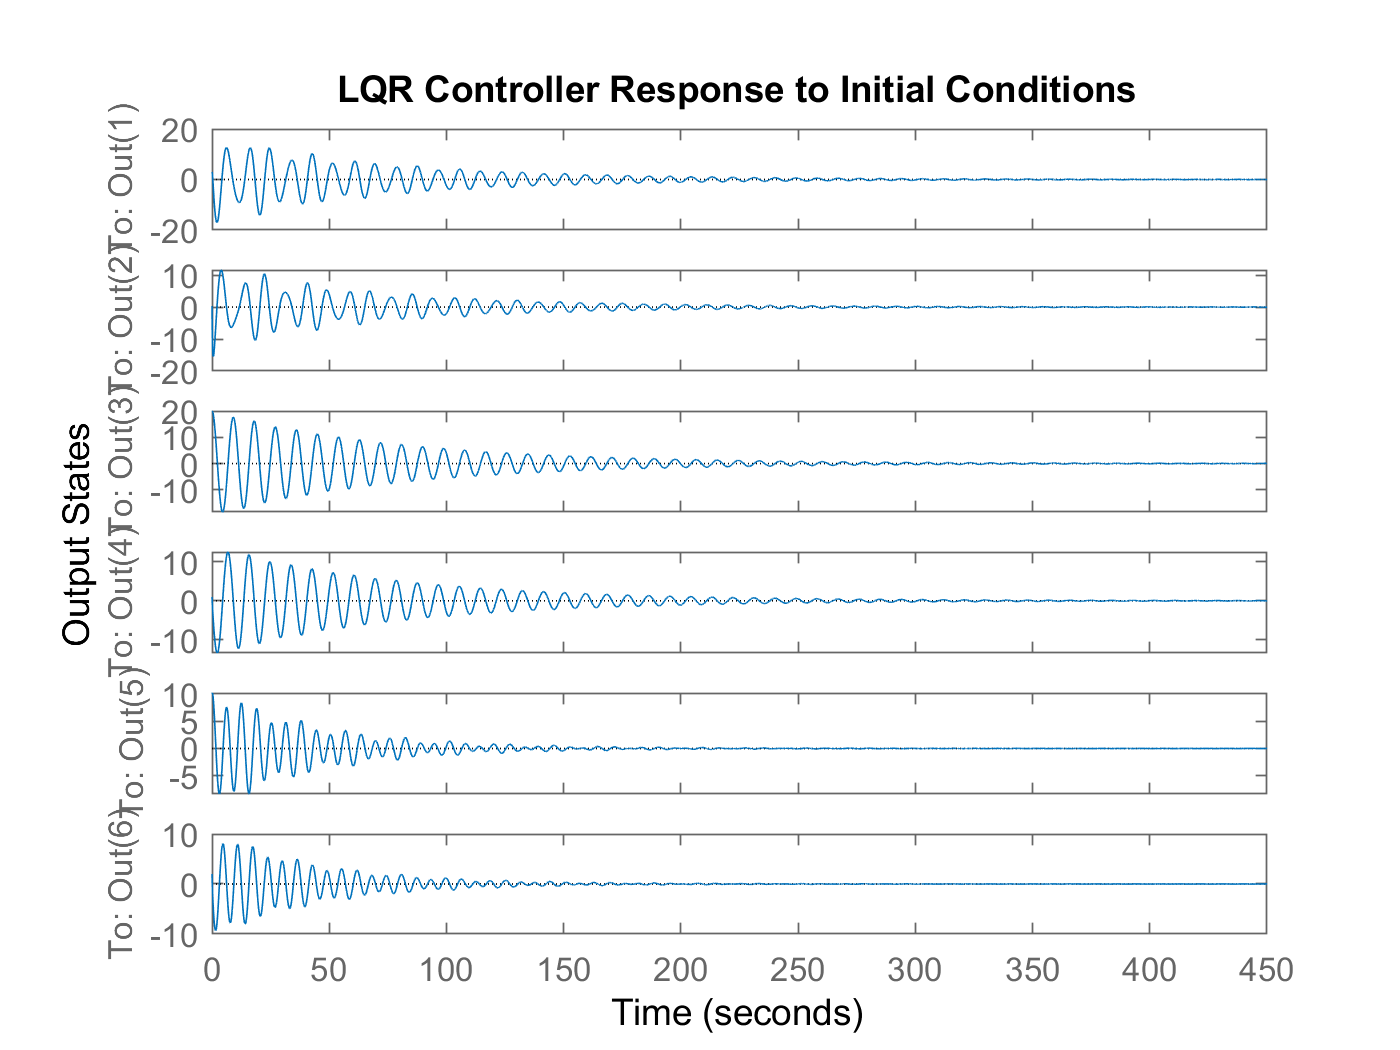

state_space = ss(New_A-(New_B*K),zeros(6,1),C,D);
initial(state_space,initial_state);
title('LQR Controller Response to Initial Conditions')
xlabel('Time')
ylabel('Output States')

disp("Eigen Values of the system after applying LQR Controller is: ")

Eigen Values of the system after applying LQR Controller is: 


Poles

Poles =   -0.0127 + 0.7000i
  -0.0127 - 0.7000i
  -0.0232 + 0.9902i
  -0.0232 - 0.9902i
  -1.0325 + 0.0000i
  -4.3249 + 0.0000i


disp("Eigen Values of the P Matrix is: ")

Eigen Values of the P Matrix is: 


eig(P)

ans = 	1.0e+06 *

    0.0043
    0.0248
    0.1927
    0.2037
    0.6297
    1.3105


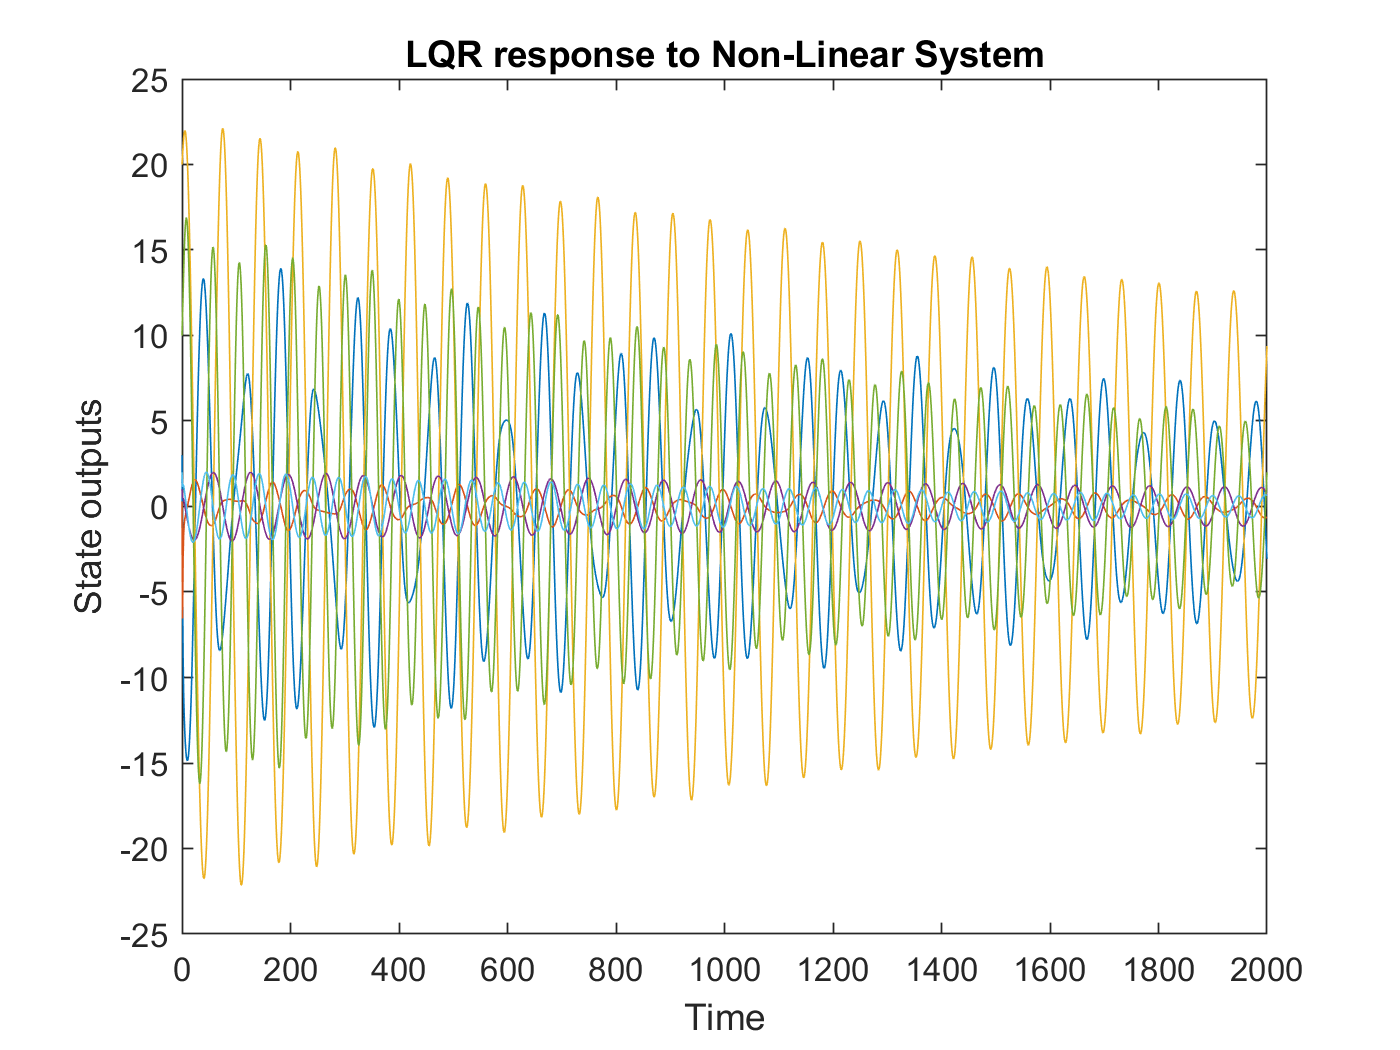

%Non Linear Model:
simulation_time = 0:1:2000;
[time,out] = ode45(@ode45_callback,simulation_time,initial_state);
figure
plot(time,out)
title('LQR response to Non-Linear System')
xlabel('Time')
ylabel('State outputs')